# **graycomatrix**

25/04/22

**Integrantes:**

Kristen Aideé Pérez Alvarez --> A00829551

Create Gray-Level Co-occurrence Matrix for Grayscale Image 

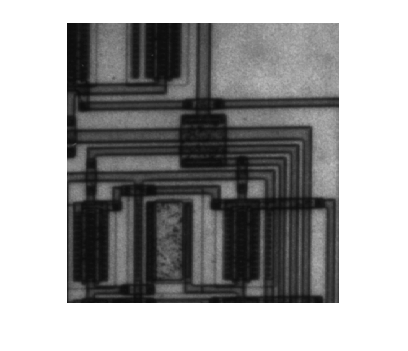

I = imread('circuit.tif'); % lee la imagen en escala de grises
imshow(I) % muestra la imagen


glcm = graycomatrix(I,'Offset',[2 0]) % calcula la matriz de co-ocurrencia de niveles de grises. Esto se hace por la proximidad horizontal de los pixeles.

glcm =        14205        2107         126           0           0           0           0           0
        2242       14052        3555         400           0           0           0           0
         191        3579        7341        1505          37           0           0           0
           0         683        1446        7184        1368           0           0           0
           0           7         116        1502       10256        1124           0           0
           0           0           0           2        1153        1435           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0


Create Gray-Level Co-occurrence Matrix (GLCM) Returning Scaled Image

I = [ 1 1 5 6 8 8; 2 3 5 7 0 2; 0 2 3 5 6 7] % se crea una matriz 3x6

I =      1     1     5     6     8     8
     2     3     5     7     0     2
     0     2     3     5     6     7



[glcm,SI] = graycomatrix(I,'NumLevels',9,'GrayLimits',[]) % calcula la matriz de co-ocurrencia de niveles de grises y de una imagen escalada. 

glcm =      0     0     2     0     0     0     0     0     0
     0     1     0     0     0     1     0     0     0
     0     0     0     2     0     0     0     0     0
     0     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     2     1     0
     0     0     0     0     0     0     0     1     1
     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1


SI =      2     2     6     7     9     9
     3     4     6     8     1     3
     1     3     4     6     7     8


Calculate GLCMs using Four Different Offsets

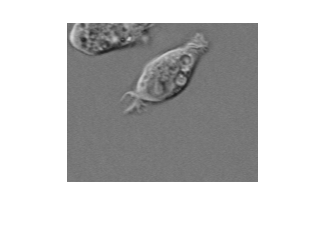

I = imread('cell.tif'); % lee la imagen en escala de grises
imshow(I) % desplega la imagen

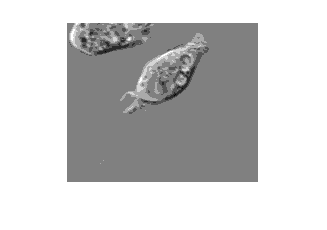


offsets = [0 1; -1 1;-1 0;-1 -1]; % se definen los desplazamientos

[glcms,SI] = graycomatrix(I,'Offset',offsets); % calcula la co-ocurrencia de niveles de grises y da una imagen escalada. Se hace un reescalado de los valores de los datos [0,1].
imshow(rescale(SI)) % muestra la imagen reescalada


whos % devuelve una matriz de cuatro GLCM

  Name           Size              Bytes  Class     Attributes

  I            159x191             30369  uint8               
  SI           159x191            242952  double              
  glcm           9x9                 648  double              
  glcms          8x8x4              2048  double              
  offsets        4x2                  64  double              



Calculate Symmetric GLCM for Grayscale Image

I = imread('circuit.tif'); % lee la imagen en escala de grises
imshow(I) % despliega la imagen


[glcm,SI] = graycomatrix(I,'Offset',[2 0],'Symmetric',true); % calcula la GLCM utilizando la opción simétrica y devuelve la imagen escalada.
% La GLCM que se crea cuando Symmetric es true es simétrica a la diagonal
glcm

glcm =        28410        4349         317           0           0           0           0           0
        4349       28104        7134        1083           7           0           0           0
         317        7134       14682        2951         153           0           0           0
           0        1083        2951       14368        2870           2           0           0
           0           7         153        2870       20512        2277           0           0
           0           0           0           2        2277        2870           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0


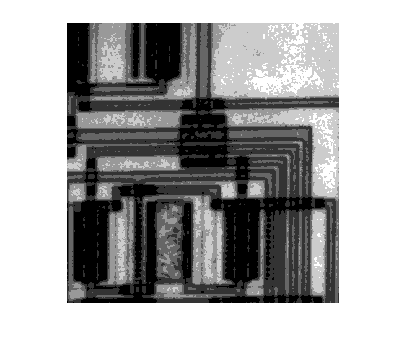


imshow(rescale(SI)) % se desplega la imagen escalada agregando un reescalamiento adicional en el rango [0,1] 



graycomatrix(I,'offset',[0 1],'Symmetric',true) % este GLCM con symmetric true es igual a la suma de las dos GLCM siguientes en donde Symmetric es false

ans =        30318        3031           1           0           0           0           0           0
        3031       33520        4133         123           0           0           0           0
           1        4133       18574        2498          22           0           0           0
           0         123        2498       16592        2103           0           0           0
           0           0          22        2103       22194        1565           0           0
           0           0           0           0        1565        3610           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0



graycomatrix(I,'offset',[0 1],'Symmetric',false) 

ans =        15159        1601           1           0           0           0           0           0
        1430       16760        2158          92           0           0           0           0
           0        1975        9287        1298           9           0           0           0
           0          31        1200        8296        1116           0           0           0
           0           0          13         987       11097         785           0           0
           0           0           0           0         780        1805           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0


graycomatrix(I,'offset',[0 -1],'Symmetric',false)

ans =        15159        1430           0           0           0           0           0           0
        1601       16760        1975          31           0           0           0           0
           1        2158        9287        1200          13           0           0           0
           0          92        1298        8296         987           0           0           0
           0           0           9        1116       11097         780           0           0
           0           0           0           0         785        1805           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
